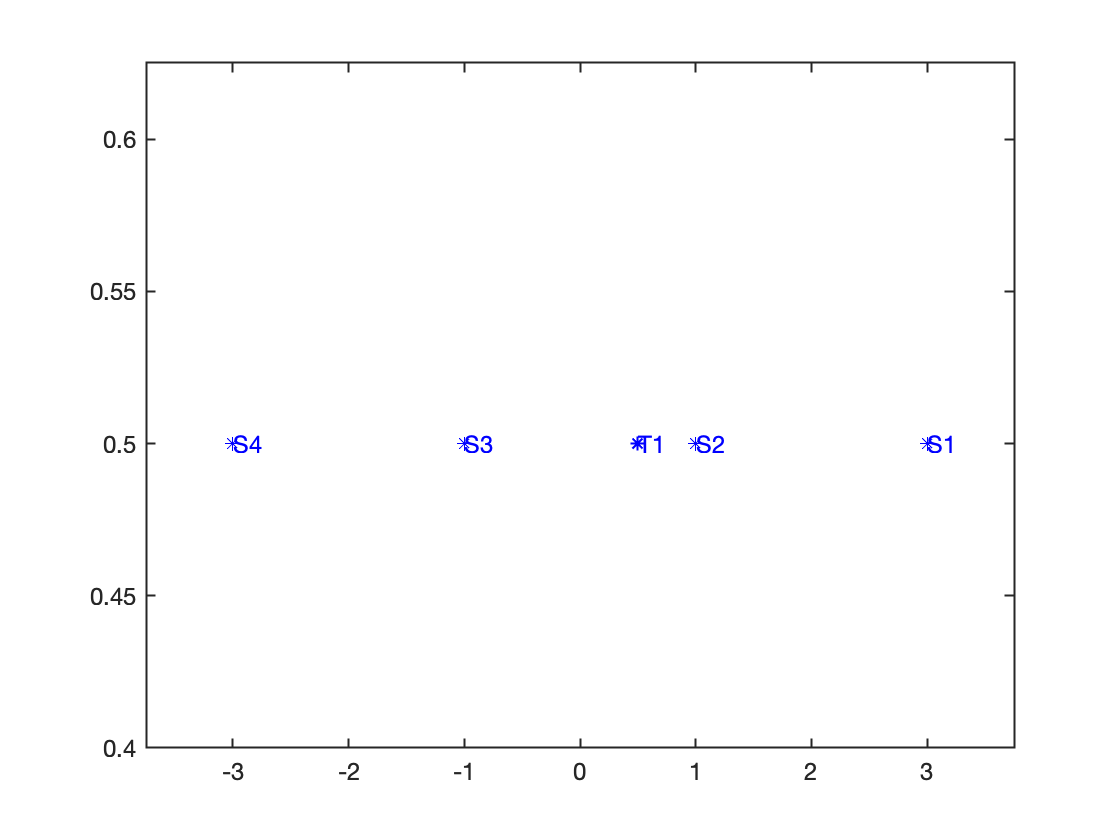

num_sensors=4;
num_target=1;
sensor_locations_1 = [1.2 1.5 1.1 -0.5 -0.9 0.9 -1.4 -1.3];
sensor_locations_2 = [2 2 2 -2 -2 -2 -2 2];
sensor_locations_3 = [3 0.5 1 0.5 -1 0.5 -3 0.5];
target_location =[0.5 0.5];



mss1=exmotion('ctcv2d');                    % load 'cv2d'(Cartesian
                                           % velocity linear time invariant model in 2D,
                                          % Ts=opt1 (0.5)) with sensor
mnl1=nl(mss1);                              
                                          % Convert to general nonlinear
                                          % model structure


sm = exsensor('toa', 4, 1, 4);
sm.th=sensor_locations_3;
sm.x0 = target_location;
mms_nl = addsensor(mnl1,sm); %Several sensors can be added sequentially
mms_nl.th = [1,1,1,-1,-1,-1,-1,1]';
mms_nl.x0 = [0.5,0.5,0.5,0.5,1];
mms_nl.pv = diag([1 1 1 1 1]);
mms_nl.pv = 0.1*mms_nl.pv; 	%reduce the velocity
mms_nl.px0 = 10*mms_nl.pv;


% y=simulate(mms_l,10);
y=simulate(mms_nl,10);


% crlb
% xcrlb=crlb(mms_l,y);
xcrlb=crlb(mms_nl,y);
% Plot only crlb
% xplot2(xcrlb,'conf',90);

% KF
% xhat1=kalman(mms_nl,y);
% Plot crlb and KF
% figure
% xplot2(xcrlb,xhat1,'conf',90);

plot(sm)
hold on

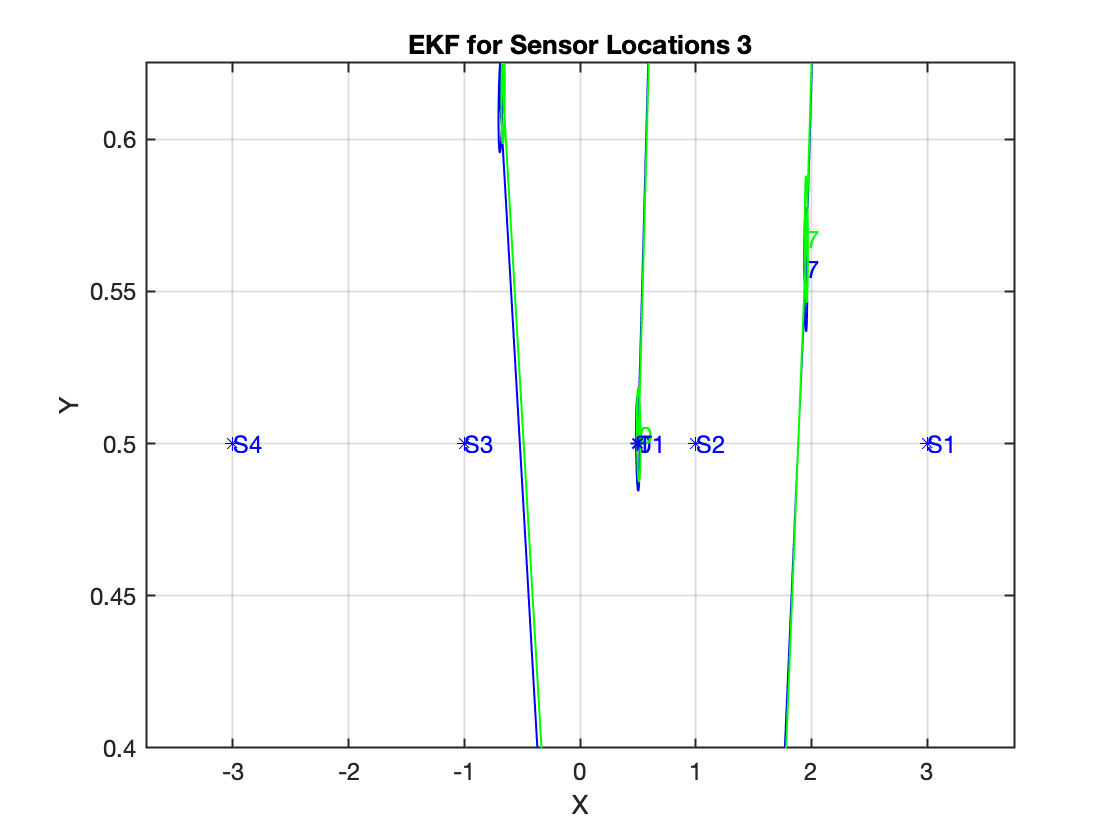

% EKF
xhat2=ekf(mms_nl,y);
% Plot crlb, KF and EKF
figure
xlim([-5 5])
ylim([-5 5])
xplot2(xcrlb,xhat2,'conf',90);
grid on
title('EKF for Sensor Locations 3');
xlabel('X');
ylabel('Y');

hold off

plot(sm)
hold on

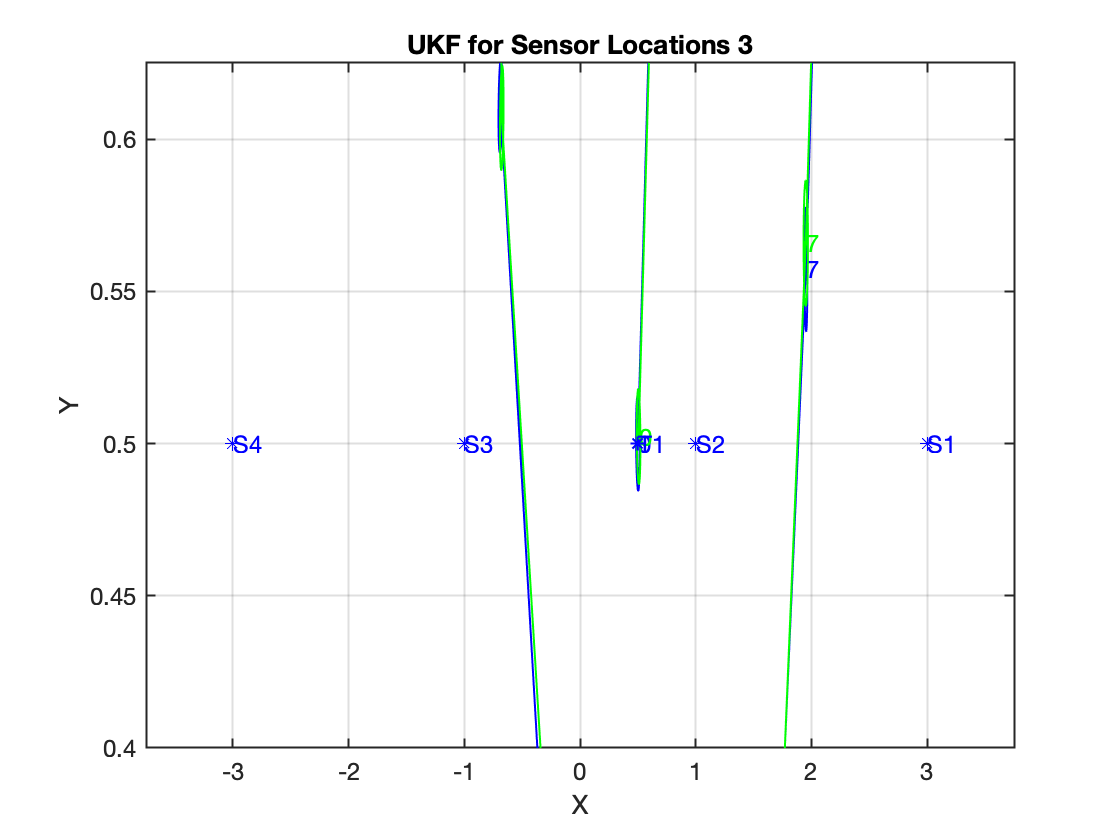

% UKF
xhat3=ukf(mms_nl,y);
% Plot crlb, KF, EKF and UKF
figure
xplot2(xcrlb,xhat3,'conf',90);
grid on
title('UKF for Sensor Locations 3');
xlabel('X');
ylabel('Y');
hold off

plot(sm)
hold on


% PF
xhat4=pf(mms_nl,y,'Np',1000);

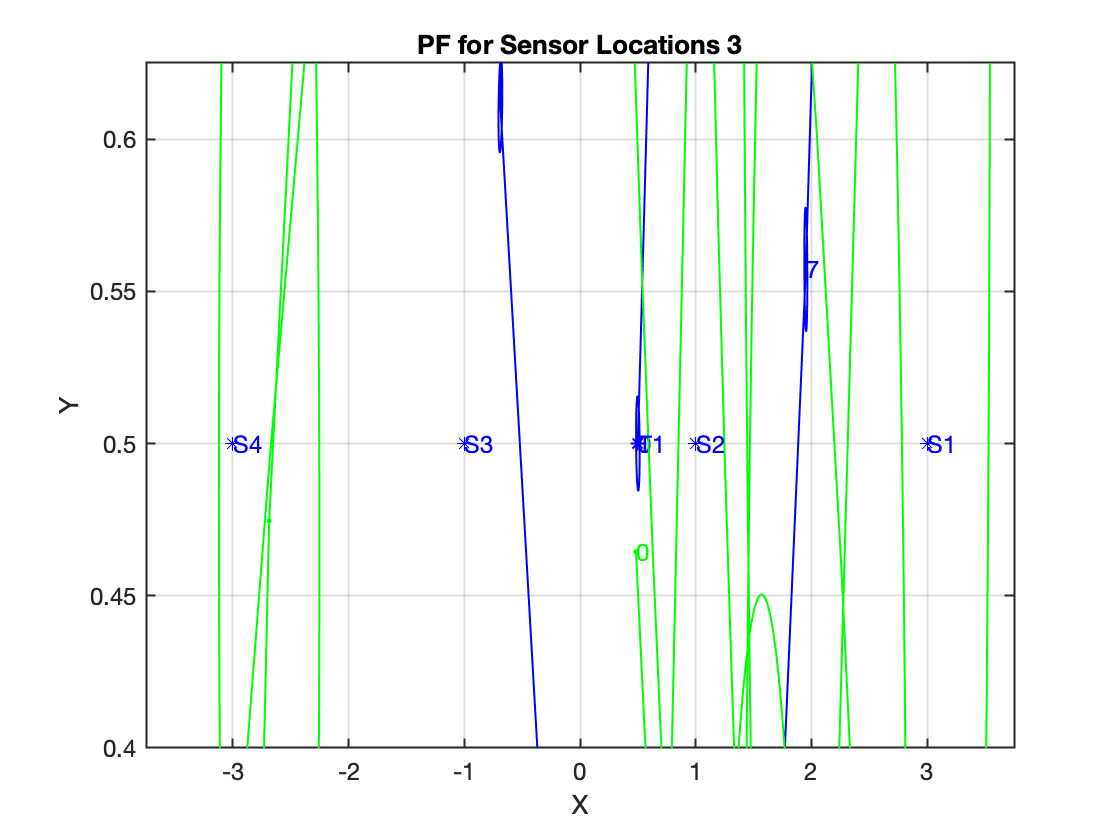

%Plot crlb, KF, EKF, UKF and PF
figure
xplot2(xcrlb,xhat4,'conf',90);
grid on
title('PF for Sensor Locations 3');
xlabel('X');
ylabel('Y');
hold on
plot(sm)